% Solve ODE-IVP using Standard RK-4 method
N = 30000;
y0 = [N*76/120;N*36/120;N*5/120;N*2/120;N*1/120];
t0 = 0;
tEnd = 5;
h = 0.1;
Nnew = (tEnd-t0)/h;

## Initializing Solutions

T = [t0:h:tEnd]';
Y = zeros(5,Nnew+1);
Y(:,1) = y0;

## Solving using RK-4 Method

for i = 1:Nnew
    yi = Y(:,i);
    k1 = TBProject(T(i), yi);
    k2 = TBProject(T(i)+h/2, yi+h*k1/2);
    k3 = TBProject(T(i)+h/2, yi+h*k2/2);
    k4 = TBProject(T(i)+h, yi+h*k3);
    yNew = yi + h/6*(k1+2*k2+2*k3+k4);
    Y(:,i+1) = yNew;
end


## Final solution and Plotting

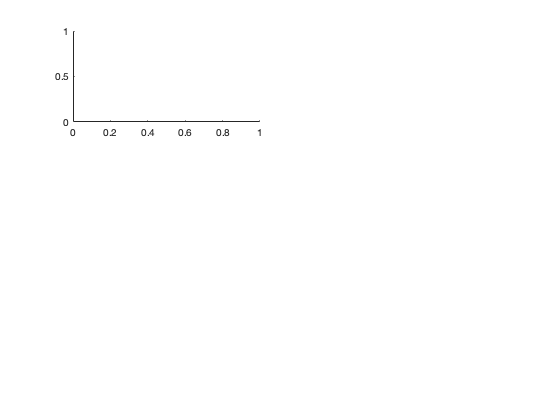




subplot(3,2,1)

plot(t,(I+L2)/N,'b-',t,(I1+L21)/N,'g*-',t,(Y(1,:)+Y(4,:))/N);

Error using plot
Vectors must be the same length.

legend('Two controls','Control U1 only','Without controls');
title('(A) (I^*+L_2^*)/N');
xlabel('Time t'); 
ylabel('(I+L2)/N');

subplot(3,2,2)
plot(t,S/N,'b-',t,S1/N,'g--*',t,Y(1,:)/N);
legend('Two controls','Control U1 only','Without controls');
title('(B) S^*/N');
xlabel('Time t'); 
ylabel('S/N');

subplot(3,2,3)
plot(t,L1/N,'b-',t,L11/N,'g*-',t,Y(2,:)/N);
legend('Two controls','Control U1 only','Without controls');
title('(C) L_1^*/N');
xlabel('Time t'); 
ylabel('L_1/N');

subplot(3,2,4)
plot(t,I/N,'b-',t,I1/N,'g*-',t,Y(3,:)/N);
legend('Two controls','Control U1 only','Without controls');
title('(D) I^*/N');
xlabel('Time t'); 
ylabel('I/N');

subplot(3,2,5)
plot(t,L2/N,'b-',t,L21/N,'g*-',t,Y(4,:)/N);
legend('Two controls','Control U1 only','Without controls');
title('(E) L_2^*/N');
xlabel('Time t'); 
ylabel('L_2/N');

subplot(3,2,6)
plot(t,R/N,'b-',t,R1/N,'g*-',t,Y(5,:)/N);
legend('Two controls','Control U1 only','Without controls');
title('(F) R^*/N');
xlabel('Time t'); 
ylabel('R/N');
